# Worksheet 4, Part 4 / 4: Assumptions and Applicability

*Author: *Zachary del Rosario, Fall 2022

*Important Note:* Worksheet 4 comes to you in **four parts**; `worksheet4_part1.mlx`, `worksheet4_part2.mlx`, `worksheet4_part3.mlx`, and `worksheet4_part4.mlx`

*Learning Objectives:* As a result of working through this notebook, you will learn:

- What *specific *assumptions the compartmental SIR model makes

- How assumptions can be "literally wrong" but "practically correct"

- How to make reasonable comparisons across random models

- How to do a modeling comparison between masking and podding!

### Additional Files

Make sure to download these additional files from Canvas and place them in the same folder as this worksheet:

- `infected.csv`

- `simulate_absir.m`

clear;

## Compartments vs Agents

Now that we've learned a lot about agent-based models and social-connectivity graphs, we can use these tools to better understand the *assumptions* that the compartmental SIR model makes.

We started out Module 1 by considering the compartmental SIR model:


$$\Delta I_t = \beta \times I_t \times S_t \\
\Delta R_t = \gamma \times I_t \\
S_{t+1} = S_t - \Delta I_t \\
I_{t+1} = I_t + \Delta I_t - \Delta R_t \\
R_{t+1} = R_t + \Delta R_t$$


**There are some** **key assumptions underlying this model.** To see this, let's focus in on the infection rule


$$\Delta I_t = \beta I_t S_t$$


What is this equation for $\Delta I_t$ really saying? *Literally*, it says the following:

    "The new number of infected persons is proportional to the current number of Infected persons, the current number of Susceptible persons, and the rate of infection $\beta$."

This update action is assumed to hold for all persons in the model, and across all time within the model. Let's probe this assumption with a few investigations using graph theory to analyze the implied social connectivity.

### The compartmental model implies certain graph properties

The compartmental SIR model can exhibit a variety of infection history curves. For instance, the following code runs the compartmental SIR model in two different scenarios with different values of $\beta$:

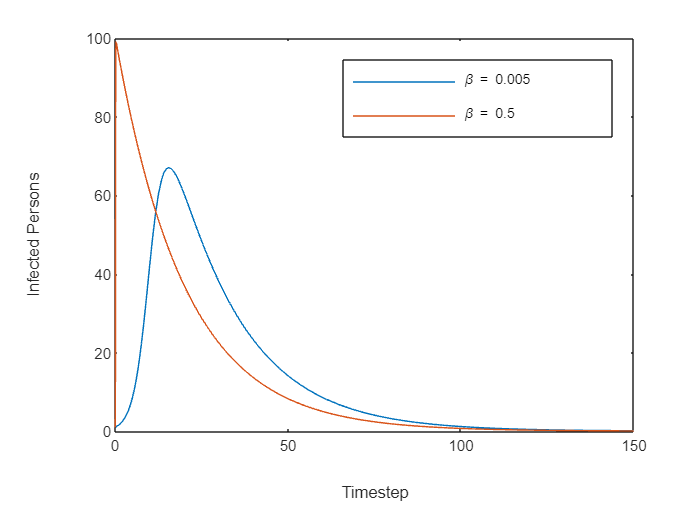

% Simulate the compartmental SIR model with two different values of \beta
[t1, Y1] = compartmental(0.005, 0.05); % \beta = 0.005
[t2, Y2] = compartmental(0.5, 0.05);   % \beta = 0.5

% Visualize the results
figure()
plot(t1, Y1(:, 2), 'DisplayName', '\beta = 0.005'); hold on
plot(t2, Y2(:, 2), 'DisplayName', '\beta = 0.5')
xlabel('Timestep')
ylabel('Infected Persons')
ylim([0, 100])
legend()

Note that in the case where $\beta = 0.5$, essentially the *entire* population becomes infected. While this is not *guaranteed* (see $\beta = 0.005$), it does show that this behavior is essentially *assumed to be possible* in the compartmental SIR model. This has important implications for the graph structure that the compartmental model assumes. You'll probe these assumptions in the next exercise.

*Note:* The compartmental SIR model does not *explicitly* consider any graph! However, we can study the assumptions that the compartmental SIR model makes *using* graphs. This is a subtle distinction that's worth noting: We are using mathematical tools from "outside" the compartmental SIR model to study the structure of that model.

### Exercise 1 / 9

Inspect the following graph. Answer the questions below.

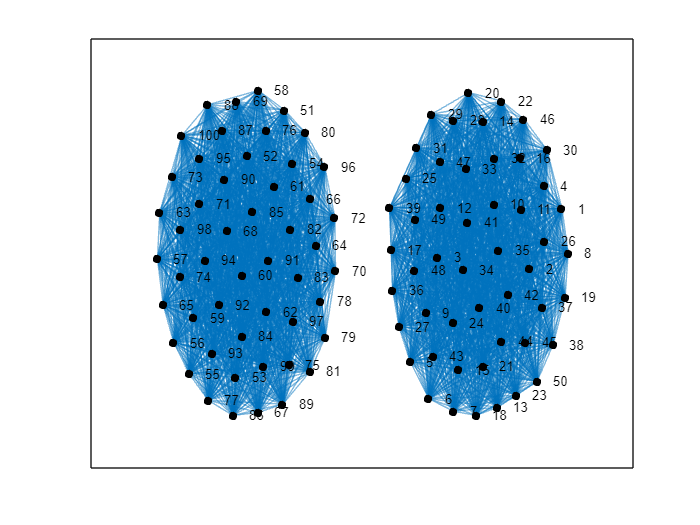

% Create a two-pod population
M_50pod = ones(50, 50) - eye(50);
M_50zs  = zeros(50, 50);
M_2pod = [
    M_50pod M_50zs;
    M_50zs  M_50pod
];

% Visualize the graph structure
Graph_2pod = graph(M_2pod);
figure(); 
h = plot(Graph_2pod, 'NodeColor', 'k', 'LineWidth', 0.1);
% NB. I use a graph layout algorithm that makes the distance between nodes
% inversely-proportional to the edge weight. This will tend to "clump" the
% pods together, which will make interpreting the graph visualization
% easier.
layout(h, 'force', 'WeightEffect', 'inverse')

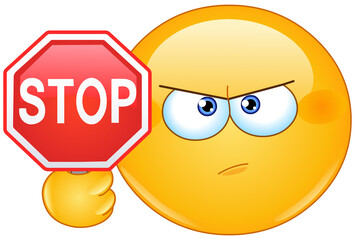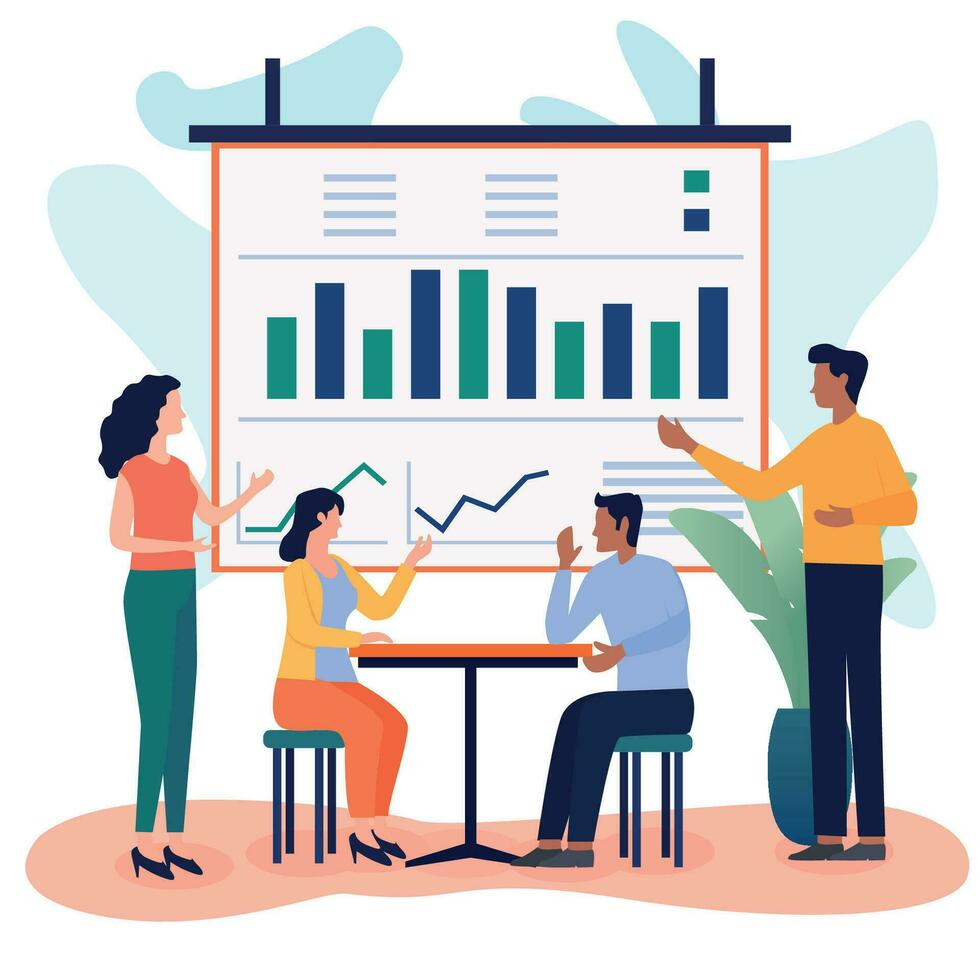

**STOP AND DISCUSS: **Talk through these with your table, and jot down notes from your discussion

- Would it be possible to get the results we saw above (with $\beta = 0.5$) in this scenario? Why or why not?

-  *(Write your ****table's ****response here) *It wouldn't be because not everyone is connected to each other. If one person becomes infected, they'll only infect the people in their pod and no one else, meaning that there will never be a time everyone is infected.

- The compartmental SIR model (essentially) assumes that the entire population can become infected, regardless of *who* is initially infected (and so long as the disease is sufficiently infective—a sufficiently large $\beta$). What must be true about the social graph corresponding to that set of assumptions?

-  *(Write your ****table's ****response here) *That everyone interacts with at least one person who is interacting with someone that person does not interact with. It also assumes everyone in the population is connected socially in some way.

The exercise above showed us one important fact about the social graph that corresponds to the compartmental SIR model. In the next exercise, we'll learn about another assumption that the compartmental model makes.

### Exercise 2 / 9

The following two graphs depict the same graph with different states of infection and susceptibility. Inspect the graphs and answer the questions below.

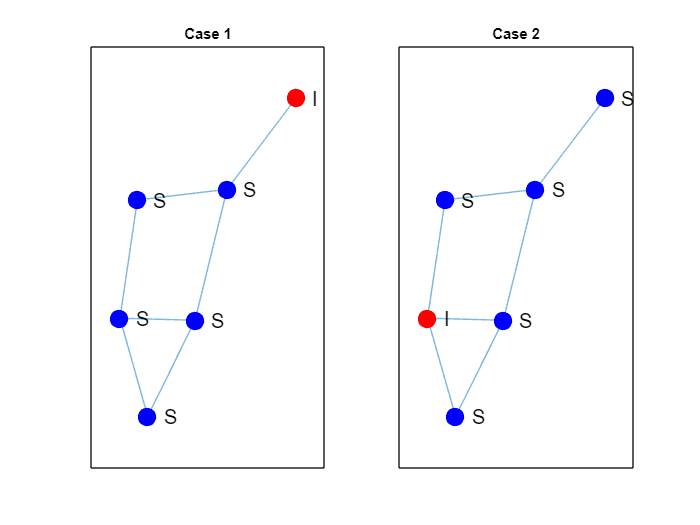

% Define the edge data
Edge_simple_start = [1 2 3 4 5 5 6];
Edge_simple_end   = [2 3 4 5 1 2 4];
% Construct the graph
Graph_simple = graph(Edge_simple_start, Edge_simple_end);
% Define a state for each node
Node_simple1_state = {'S' 'S' 'S' 'S' 'S' 'I'}';
Node_simple1_color = [
    [0 0 1];
    [0 0 1];
    [0 0 1];
    [0 0 1];
    [0 0 1];
    [1 0 0]
];
% Define a second scenario
Node_simple2_state = {'S' 'I' 'S' 'S' 'S' 'S'}';
Node_simple2_color = [
    [0 0 1];
    [1 0 0];
    [0 0 1];
    [0 0 1];
    [0 0 1];
    [0 0 1]
];

% Visualize
figure(); subplot(1, 2, 1)
h = plot(Graph_simple, 'NodeColor', Node_simple1_color, 'MarkerSize', 10, 'NodeFontSize', 12);
labelnode(h, 1:6, Node_simple1_state)
title('Case 1')

subplot(1, 2, 2)
h = plot(Graph_simple, 'NodeColor', Node_simple2_color, 'MarkerSize', 10, 'NodeFontSize', 12);
labelnode(h, 1:6, Node_simple2_state)
title('Case 2')

- In Case 1, what is the *maximum* number of new infected persons (highest possible value of $\Delta I_t$), based on the current state of the model? Why?

-  *(Write your response here) *2, because each person is connected to at most 2 people.

- In Case 2, what is the *maximum* number of new infected persons (highest possible value of $\Delta I_t$), based on the current state of the model? Why?

-  *(Write your response here) *3, because the maximum number of people one person is conncected to is 3.

- Is it possible for the equation $\Delta I_t = \beta I_t S_t$ to adequately model this social situation? Why or why not? (Assume a fixed value of $\beta$).

-  *(Write your response here) *No, because the equation assumes everyone is connected to everyone else, and in order to model this situation $\beta$ would have to change each timestep because there would be a new number of infected persons after each timestep.

- What would need to be true about the social connections among individuals in order for the expression $\Delta I_t = \beta I_t S_t$ to be an adequate model? *Hint:* Think about the *number *of connections each individual should have.

-  *(Write your response here) *Every individual should be connected to every other individual.

### Exercise 3 / 9

Design a graph that would represent a situation of social connectivity where the following assumption would be true:

   "The new number of infected persons is proportional to the current number of Infected persons, the current number of Susceptible persons, and the rate of infection $\beta$."

**STOP & DISCUSS:** Before you implement code, discuss with your tablemates what this adjacency matrix would look like? How is it similar to adjacency matrices in previous parts of the worksheet? 

To simplify things: make all edge weights one, consider a 100-person population, and represent your graph by its adjacency matrix. Use the insights you gained from the previous exercises. Once you have constructed the correct graph (use the assertions to check your graph), answer the questions below.

❗ *Hint*: You might not yet realize it, but you've already constructed this graph multiple times in the previous parts of the worksheet! ❗

% Use a population size of 100
n_population = 100;

% TODO: Construct the adjacency matrix that would
M_compartmental = ~eye(100); % Fix this

% NOTE: Do not edit these lines; 
% use this to check your work
assert(all(diag(M_compartmental) == 0), 'The diagonal of M should be zeros')
assert(sum(M_compartmental, 'all') == 1e4 - 100, 'The matrix M should have 9900 nonzero entries')
disp('Assertions passed!')

Assertions passed!


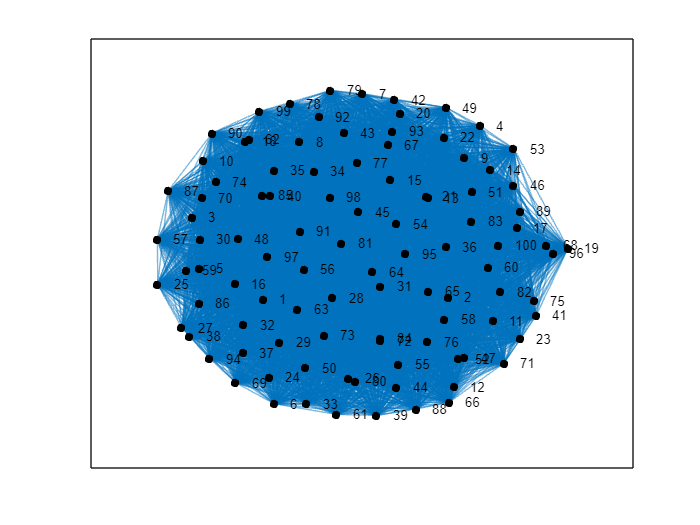


% Visualize the graph
Graph_pods = graph(M_compartmental);
figure()
plot(Graph_pods, 'NodeColor', 'k')

- What kind of graph is this?

-  *(Write your answer here) *It is a connected graph.

- Look back at Part 3 of Worksheet 4, Exercise 5: the SNAP graph of real social network data. *Qualitatively*, how does the SNAP graph compare with the graph that you constructed? How well does the graph you constructed match real social network data?

-  *(Write your answer here) *It doesn't match the data very well because in the SNAP graph most people were only connected to a small number of other poeple, with some being connected to as little as 1 person or even no people. The graph I constructed does not match real social network data that well because everyone is connected to almost everyone else, which just isn't how the real world works.

- What assumption does the compartmental SIR model make about social connectivity?

-  *(Write your answer here) *That all people are connected to all other people.

### What do the compartmental parameters mean?

We have two different models that seek to model the same situation. However, they approach modeling from *verThy different *perspectives. One consequence of this difference is that *the parameters of the two models are numerically incomparable*.

For example, let's try running both the compartmental and agent-based SIR models with "the same" parameter values:

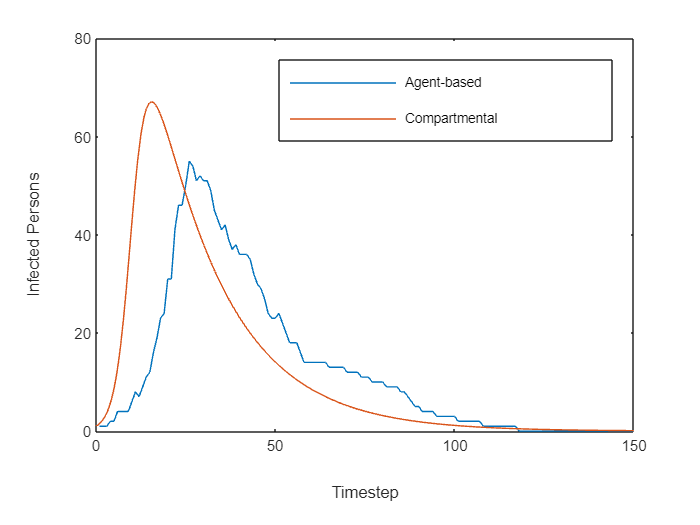

% Set parameter values
infection_rate = 0.005; recovery_rate = 0.05; % Agent-based model
          beta = 0.005;         gamma = 0.05; % Compartmental model

% Simulate agent-based model
Iv1 = zeros(n_population, 1);
Iv1(1) = 1;
rng(101)
[~, Ih, ~] = simulate_absir(M_compartmental, Iv1, 150, infection_rate, recovery_rate);
I_count = sum(Ih, 1);

% Simulate the compartmental model
[t, Y] = compartmental(beta, gamma);

% Visualize
figure()
plot(I_count, 'DisplayName', 'Agent-based'); hold on;
plot(t, Y(:, 2), 'DisplayName', 'Compartmental')
legend()
xlabel('Timestep')
ylabel('Infected Persons')

Note that these results are **quite different!** That's because the parameters are implemented differently:

- $\beta$ controls the **deterministic** infection rate, while `infection_rate` controls a **random** effect, and

- $\gamma$ controls the **deterministic** recovery rate, while `recovery_rate` controls a **random** effect.

While the parameters are **not equal**, they do play similar roles in the different models:

- Both $\beta$ and `infection_rate` describe how quickly the disease spreads from person to person.

- Both $\gamma$ and `recovery_rate` describe how quickly an individual recovers from the disease.

Since the parameters play familiar roles, we can *attempt* to fit the parameter values of the compartmental model to match the *results* of the agent-based model. You'll do this in the next exercise.

### Exercise 4 / 9

Modify the compartmental model's parameters $\beta, \gamma$ to *best* match the results from the agent-based model. Do not try to match the two exactly (it is impossible, as you'll soon see).When you think you have a match, try running the section again - is the match still good?  Answer the questions below.

*Hint:* If the agent-based trajectory seems to "disappear"—don't panic! Just click 'Run Section' again.

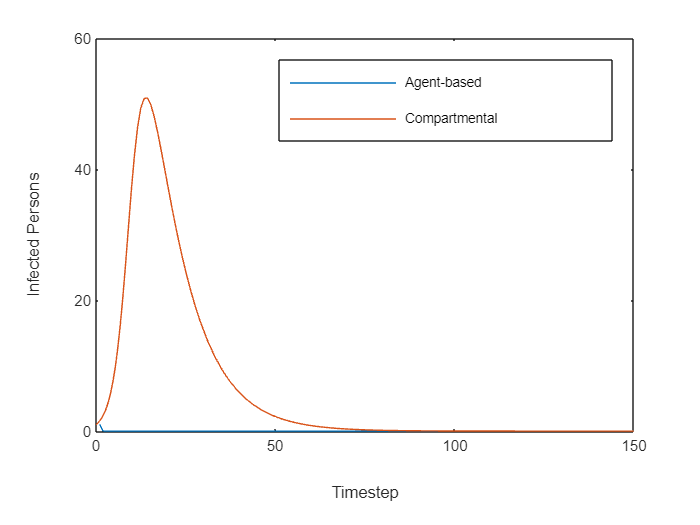

% TODO: Modify the compartmental model's parameters to *approximately*
% match the agent-based model. Note that it will be *impossible* to exactly
% match the two!!!
beta = 0.0055; gamma = 0.1;

% NOTE: Do not edit these parameters, or the code below
infection_rate = 0.01; recovery_rate = 0.1;

% Normalize the matrix
M_compartmental_normalized = M_compartmental / n_population;

% Simulate agent-based model
Iv1 = zeros(n_population, 1);
Iv1(1) = 1;
[Sh, Ih, Rh] = simulate_absir(M_compartmental, Iv1, 150, infection_rate, recovery_rate);
I_count = sum(Ih, 1);

% Simulate the compartmental model
[t, Y] = compartmental(beta, gamma);

% Visualize
figure()
plot(I_count, 'DisplayName', 'Agent-based'); hold on;
plot(t, Y(:, 2), 'DisplayName', 'Compartmental')
legend()
xlabel('Timestep')
ylabel('Infected Persons')

- Are the results from the agent-based model the same each time you run the model? Why is this?

-  *(Write your response here) *No, because the rate of infection and recovery is random in the agent-based model.

- What are some reasons why it is not possible to exactly match the results between the compartmental and agent-based models? *Hint*: There are more reasons than the reason that follows from the previous question....

-  *(Write your response here) *It is not possible because the infection and recovery rates are randomly generated, and the agent based model has infection and recovery rates that change with each time step, meaning there isn't a long, smooth, continuous decrease or increase thorughout the graph.

### What does the compartmental model actually compute!?!?

Hopefully, the previous exercise raises an important question in your mind: "What does the compartmental model actually compute?!?!"

We'll work on answering this question, but we'll come at it from a peculiar angle. Since the agent-based model is a random model, let's run it *multiple times* with exactly the same settings, and study the *variation* across the resulting infection curves.

❗*Note*: A single run of a random simulation is called a *realization*. A set of multiple realizations is called a *sample*.❗

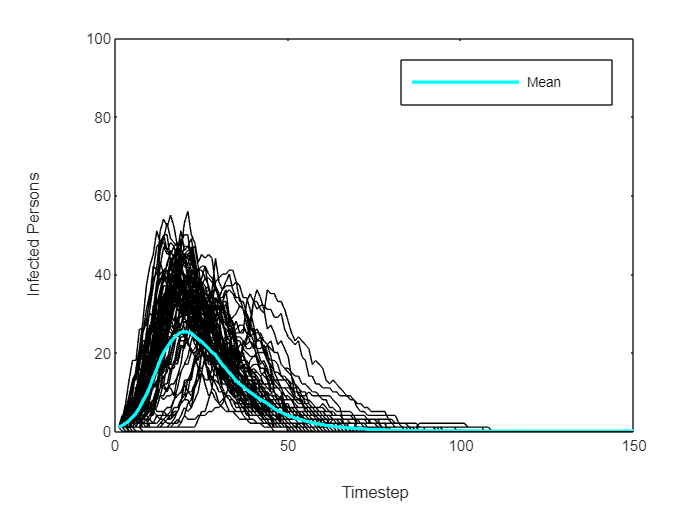

% Set the number of replications for the agent-based model
n_realizations = 100;
% Run each simulation for 150 timesteps
T_simulation = 150;
% Reserve space for simulation results
I_ensemble = zeros(T_simulation, n_realizations);
% Set the random seed. This is something we'll talk about in the next
% module.
rng(101)
% Set parameter values
infection_rate = 0.5; recovery_rate = 0.1;

% Generate the sample of results
for i = 1 : n_realizations
    % Run a single simulation
    [Sh, Ih, Rh] = simulate_absir(M_compartmental_normalized, Iv1, T_simulation, infection_rate, recovery_rate);
    % Summarize and store the infection history
    I_ensemble(:, i) = sum(Ih, 1);
end

% Compute the mean
I_mean = mean(I_ensemble, 2);

% Visualize
figure()
plot(I_ensemble, 'k-', 'LineWidth', 0.1, 'HandleVisibility', 'off'); hold on;
plot(I_mean, 'c-', 'LineWidth', 2.0, 'DisplayName', 'Mean');
xlabel('Timestep')
ylabel('Infected Persons')
ylim([0 100])
legend()

This plot shows each realization from the agent-based model as a black curve. We've also computed the mean across the entire sample of realizations as a cyan line. Let's spend a bit of time interpreting these results

### Exercise 5 / 9

Answer the following questions based on the plot above.

- We might want to make a prediction based on the agent-based model, say for the number of infected persons at timestep 50. Can we say there is one "true" value for the number of infected persons at timestep 50?

- *    (Write your response here) *No, because it will change with every realization.

There's a more convenient way to summarize the sample of results; we can compute and plot [*quantiles*](https://en.wikipedia.org/wiki/Quantile) across the sample. Quantiles allow us to define low and high values (not min and max) that occured within the sample.

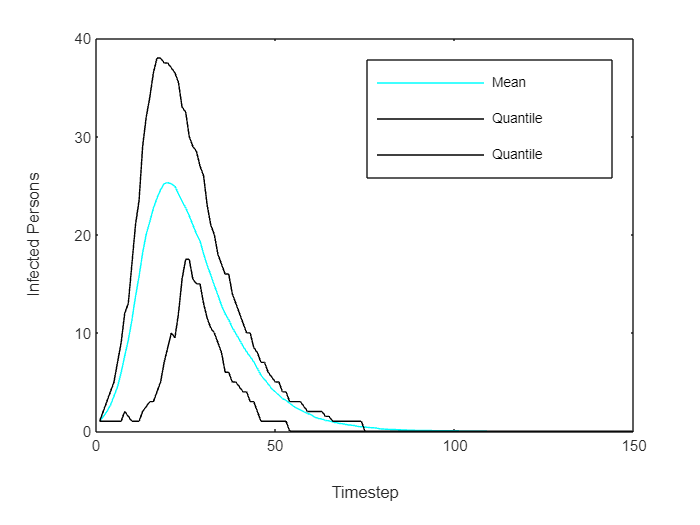

% Plot quantiles
I_lo = quantile(I_ensemble, 0.25, 2); % Lower (25%) quantile
I_up = quantile(I_ensemble, 0.75, 2); % Upper (75%) quantile

figure();
plot(I_mean, 'c', 'DisplayName', 'Mean'); hold on;
plot(I_lo, 'k', 'DisplayName', 'Quantile')
plot(I_up, 'k', 'DisplayName', 'Quantile')
legend()
xlabel('Timestep')
ylabel('Infected Persons')

The mean gives us a sense of "typical" behavior, while the lower and upper quantiles give us a sense for variability in the results. Both features—typical behavior and variability in behavior—are important for making sense of the agent-based model's results.

Let's try to match the compartmental results to these *summaries* of the agent-based model results.

### Exercise 6 / 9

Tweak the compartmental model parameters to match *all* of the summary curves: mean, lo, and up. Answer the questions below.

*Hint*: Use 'Run Section' rather than 'Run' to run only this section. This will be helpful because running this section alone will not regenerate the ensemble. You may also find it helpful to switch to the 'Output on right' setting for your LiveScript (it's just easier to see both the parameter values and result figure simultaneously).

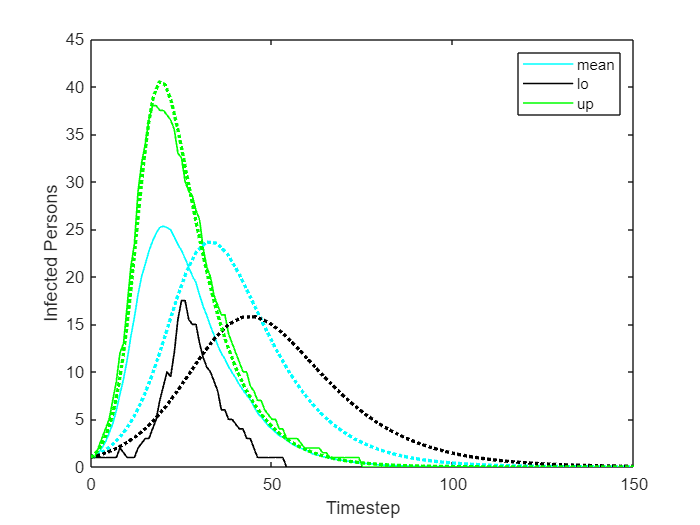

% TODO: Modify the compartmental model's parameters to *approximately*
% match the agent-based model. Do this process for all three sample
% summaries: the mean trajectory, the lo, and the up.

% Note that it will *still* be *impossible* to exactly match every result!
beta_lo = 0.002; gamma_lo = 0.1;
beta_mu = 0.0025; gamma_mu = 0.1;
beta_up = 0.004; gamma_up = 0.1;

% Simulate the compartmental model
[t_lo, Y_lo] = compartmental(beta_lo, gamma_lo);
[t_mu, Y_mu] = compartmental(beta_mu, gamma_mu);
[t_up, Y_up] = compartmental(beta_up, gamma_up);

% Visualize the results
figure();
% The ensemble results
plot(I_mean, 'c', 'LineWidth', 1, 'DisplayName', 'mean'); hold on;
plot(I_lo, 'k', 'LineWidth', 1, 'DisplayName', 'lo')
plot(I_up, 'g', 'LineWidth', 1, 'DisplayName', 'up')
% The fitted results
plot(t_mu, Y_mu(:, 2), 'c:', 'LineWidth', 2, 'HandleVisibility', 'off')
plot(t_lo, Y_lo(:, 2), 'k:', 'LineWidth', 2, 'HandleVisibility', 'off')
plot(t_up, Y_up(:, 2), 'g:', 'LineWidth', 2, 'HandleVisibility', 'off')
legend()
xlabel('Timestep')
ylabel('Infected Persons')

- How well are you able to fit the `mean` trajectory?

- *    (Write your response here) *Not that well, I was able to get the right number of max infected persons but at the wrong timestep.

- How well are you able to fit the `up` trajectory?

- *    (Write your response here) *Almost exactly.

- How well are you able to fit the `lo` trajectory? Why?

- *    (Write your response here) *Similarly to the mean, I was able to get the right max infected at the wrong timestep.

**STOP & DISCUSS: ** Discuss how you approached the matching with your tablemates, and then share the parameter values that you determined. Are they the same for each person? 

(Write your table's parameter values here) Not in class but with the few people I talked to they were pretty similar.

From this exercise, we can see that the compartmental model produces results that can adequately represent *summaries* over multiple agent-based model runs. Collecting what we've seen so far, we can conclude the following:

- The compartmental SIR model **cannot** repeatably match the particular results of any single run (realization) from the agent-based model. This is because the compartmental model is deterministic, while the agent-based model is random.

- The compartmental SIR model **can** match a **summary** over a **sample** of agent-based model results, such as the mean or an upper-quantile. (It turns out that summaries over random phenomena are deterministic—we'll discuss this more in Worksheet 5!)

These are useful comparisons between the two models, but it is even more important to consider how the compartmental model relates to the physical (real) world:

- The compartmental SIR model makes strong assumptions about the social connectivity of people *and* it is only a suitable model for summary behavior (such as the mean over many realizations).

This might lead you to make a hasty conclusion....

## "Literally" Correct vs "Practically" Correct

*Or, "All models are wrong, some are useful."* (G.E.P. Box)

At this point, you might be thinking "Wow, the compartmental SIR model is wrong! This must be a crappy model!"

This is exactly the wrong conclusion to draw from this worksheet!!!

Now that we've talked *in detail* about how the SIR model makes unrealistic assumptions, let's talk about *why "unrealistic" assumptions are still useful*.

### Homogeneous social connectivity is sometimes a "good enough" model!

We've made a big deal out of the difference in social connectivity across different cases—but how much of a *practical* difference does this make for the progression of an infection?

Let's compare agent-based SIR results between two seemingly different scenarios: 10-person pods with an infectivity difference of 100x between those in and outside the pods. The graph for the podding scenario looks considerably different from the *homogeneous* graph assumed by the compartmental model:

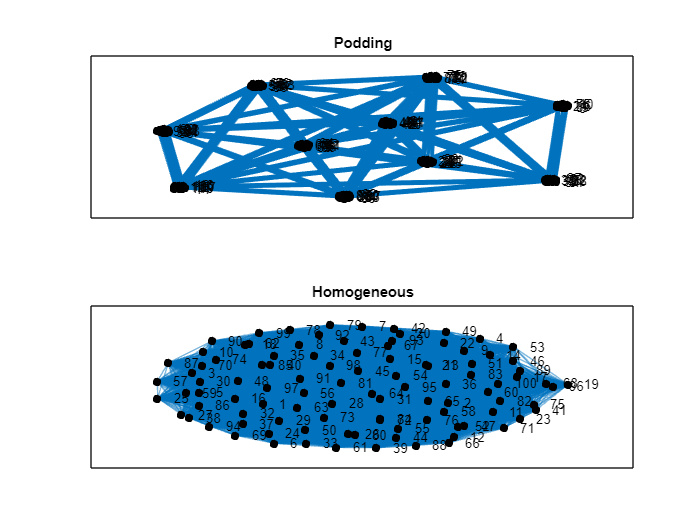

% Construct a very intense "podding" scenario
% Note: We'll learn about this helper function a little later
M_pods = make_adj_pods(10, 10, 100) / 100;

% Visualize the graph structure
Graph_pods = graph(M_pods);
Graph_hom  = graph(M_compartmental);
figure(); subplot(2, 1, 1)
h = plot(Graph_pods, 'NodeColor', 'k', 'LineWidth', 0.1);
layout(h, 'force', 'WeightEffect', 'inverse')
title('Podding')

subplot(2, 1, 2)
h = plot(Graph_hom, 'NodeColor', 'k', 'LineWidth', 0.1);
layout(h, 'force', 'WeightEffect', 'inverse')
title('Homogeneous')

However, if we compare the results of an *infection* across both graphs, we see that the results are not that different!

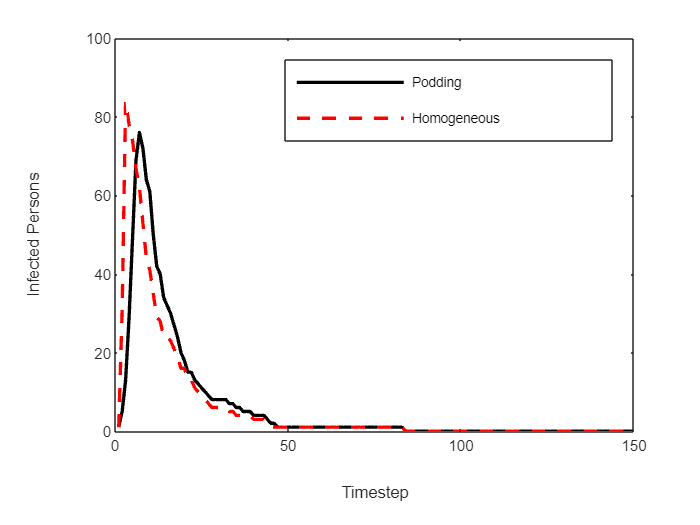

% Simulate both scenarios using the agent-based SIR model
rng(101)
[~, Ih_pods, ~] = simulate_absir(M_pods, Iv1, 150, infection_rate, recovery_rate);
rng(101)
[~, Ih_hom, ~] = simulate_absir(M_compartmental, Iv1, 150, infection_rate, recovery_rate);

I_count_pods = sum(Ih_pods, 1);
I_count_hom = sum(Ih_hom, 1);

figure();
plot(I_count_pods,  'k', 'LineWidth', 2, 'DisplayName', 'Podding'); hold on
plot(I_count_hom, 'r--', 'LineWidth', 2, 'DisplayName', 'Homogeneous')
xlabel('Timestep')
ylabel('Infected Persons')
legend()

While the homogeneous graph (assumed by the compartmental model) is *literally* wrong, it *practically* gives results very similar to this seemingly dramatic case of podding! While the podding scenario does reduce the peak number of infected individuals, it still results in a dramatic infection spike, and the infection ends at essentially the same time as the Homogeneous scenario.

This highlights a *very important *lesson about modeling:

- No modeling assumption is **literally** correct. What matters is that our assumptions are **sufficiently accurate** for our modeling question.

In this case, if we wanted to get the infection peak *exactly right* (a foolish objective, but stick with me here), the Homogeneous graph model would clearly be insufficient. However, if we wanted to get the peak approximately right, or were interested in when the infection wave would end, the Homogeneous graph would be sufficiently accurate.

Of course, there are limits to the Homogeneous graph model. If we consider an even more dramatic case of podding (4-persons to a pod), then the infection behaviors are even more dramatically different:

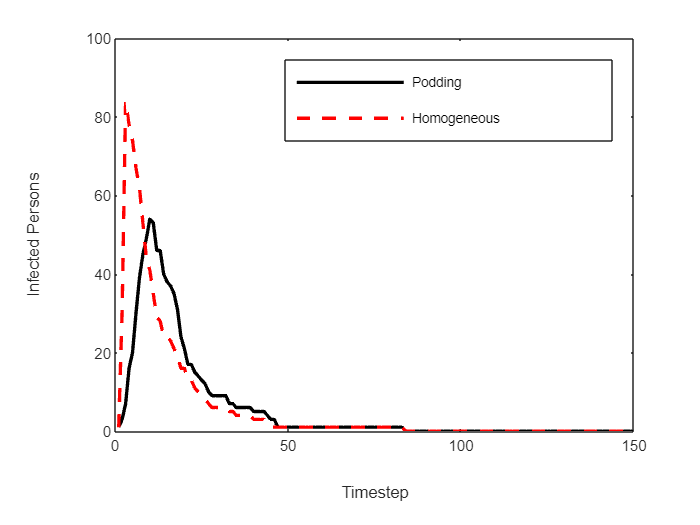

% Simulate both scenarios using the agent-based SIR model
M_pods01 = make_adj_pods(4, 25, 100) / 100;
rng(101)
[~, Ih_pods01, ~] = simulate_absir(M_pods01, Iv1, 150, infection_rate, recovery_rate);
rng(101)
[~, Ih_hom, ~] = simulate_absir(M_compartmental, Iv1, 150, infection_rate, recovery_rate);

I_count_pods01 = sum(Ih_pods01, 1);
I_count_hom = sum(Ih_hom, 1);

figure();
plot(I_count_pods01,  'k', 'LineWidth', 2, 'DisplayName', 'Podding'); hold on
plot(I_count_hom, 'r--', 'LineWidth', 2, 'DisplayName', 'Homogeneous')
xlabel('Timestep')
ylabel('Infected Persons')
legend()

Part of the *skill* in effective modeling is choosing assumptions that are *appropriate* for the modeling question at hand. This will likely require a lot of critical thought and testing (verification and validation) of your model.

## Podding vs Masking

In the previous part of Worksheet 4 we mentioned doing a comparison between masking and podding. Let's finally make that comparison!

Previously, we learned how to construct graphs of various types by building up their adjacency matrices. I've implemented a "helper function" `make_adj_pods` to help construct an adjacency matrix corresponding to pods of different sizes and relative infection strength. We can call it using the following syntax:

% Choose the pod parameters
n_per_pod = 3;   % Number of persons in each pod
n_pods = 2;      % Number of pods
pod_effect = 10; % Relative "strength" of connections within the pod;
                 % Higher values (>>1) lead to more transmission within the
                 % pod

% Generate the desired adjacency matrix
M_pod_test = make_adj_pods(n_per_pod, n_pods, pod_effect)

M_pod_test =      0    10    10     1     1     1
    10     0    10     1     1     1
    10    10     0     1     1     1
     1     1     1     0    10    10
     1     1     1    10     0    10
     1     1     1    10    10     0


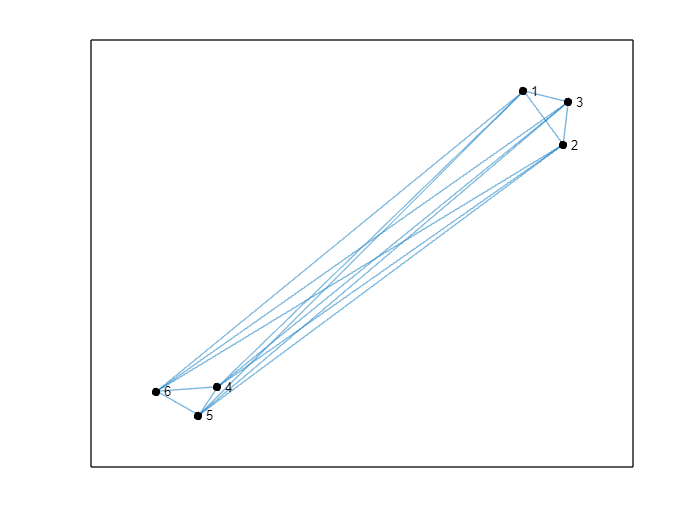


% Visualize the graph
Graph_pod_test = graph(M_pod_test);
figure()
h = plot(Graph_pod_test, 'NodeColor', 'k', 'LineWidth', 0.1);
layout(h, 'force', 'WeightEffect', 'inverse')

One way we could model masking across pods is to make the between-mask edge weights much smaller. For instance, the following two adjacency matrices are meant to correspond to podding with no mask-wearing outside the pod. The assumption here is that limiting one's contact with people outside the pod reduces the transmission effect by a factor of 50; this is due to extremely limited contact with people outside one's pod. The masked model put everyone in the same pod but cuts the transmission effect by a factor of 10; this is due to regular contact with others, but masked.

% No-mask, podded graph
make_adj_pods(n_per_pod, n_pods, 50) / 50

ans =          0    1.0000    1.0000    0.0200    0.0200    0.0200
    1.0000         0    1.0000    0.0200    0.0200    0.0200
    1.0000    1.0000         0    0.0200    0.0200    0.0200
    0.0200    0.0200    0.0200         0    1.0000    1.0000
    0.0200    0.0200    0.0200    1.0000         0    1.0000
    0.0200    0.0200    0.0200    1.0000    1.0000         0


% Masked, un-podded graph
make_adj_pods(6, 1, 1) / 10

ans =          0    0.1000    0.1000    0.1000    0.1000    0.1000
    0.1000         0    0.1000    0.1000    0.1000    0.1000
    0.1000    0.1000         0    0.1000    0.1000    0.1000
    0.1000    0.1000    0.1000         0    0.1000    0.1000
    0.1000    0.1000    0.1000    0.1000         0    0.1000
    0.1000    0.1000    0.1000    0.1000    0.1000         0


Six people is not a very realistic population size. Let's make similar graphs, but for a population of 100 persons.

### Exercise 7 / 9

Use the helper function `make_adj_pods()` to construct an adjacency matrix for the 100-person population with no pods, but masking among all people (use an effect of `1 / 10` to model masking, like above).

% NOTE: No need to change this; here's the no-mask, podded graph
M_pod5_nomasks = make_adj_pods(5, 20, 50) / 50;

% TODO: Make the unpodded-but-masked adjacency matrix for a 100-person
% population
M_nopod_masked = make_adj_pods(100,1,1)/10; % FIX THIS

% NOTE: Do not edit these lines; 
% use this to check your work
assert(all(diag(M_nopod_masked) == 0), 'The diagonal of the adjacency matrix should be zeros')
assert(abs(sum(M_nopod_masked, 'all') - 990) < 1e-3, 'The adjacency matrix should have off-diagonal entries of 0.1')
disp('Assertions passed!')

Assertions passed!


Next we'll use your adjacency matrix to run some infection simulations.

### Comparing model runs

We've set up two different versions of the agent-based model, but it would be a **very bad idea** to compare single realizations from both models:

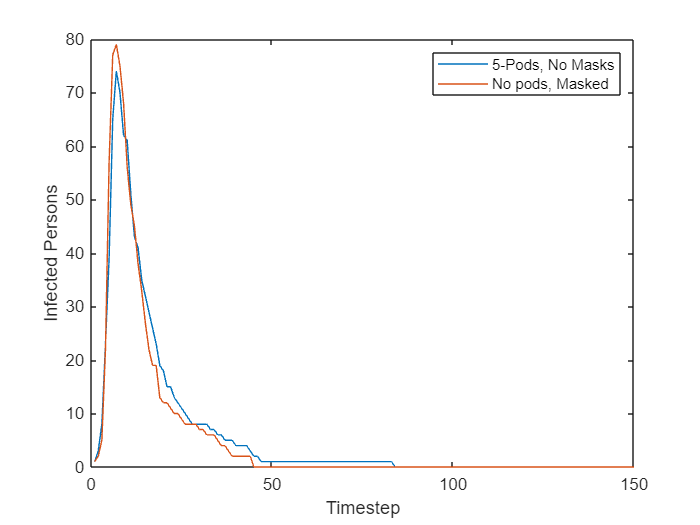

% THE FOLLOWING IS A TERRIBLE IDEA
% Set parameter values
infection_rate = 0.5; recovery_rate = 0.1; tend = 150;

% Simulate
rng(101)
[~, Ih_pod5_nomasks, ~] = simulate_absir(M_pod5_nomasks, Iv1, tend, infection_rate, recovery_rate);
[~, Ih_nopod_masked, ~] = simulate_absir(M_nopod_masked, Iv1, tend, infection_rate, recovery_rate);

% Visualize
I_count_pod5_nomasks = sum(Ih_pod5_nomasks, 1);
I_count_nopod_masked = sum(Ih_nopod_masked, 1);

figure();
plot(I_count_pod5_nomasks, 'DisplayName', '5-Pods, No Masks'); hold on;
plot(I_count_nopod_masked, 'DisplayName', 'No pods, Masked')
xlabel('Timestep')
ylabel('Infected Persons')
legend()

To see why this is **such a bad idea**, let's look at another example. If we compare two runs **from an identical model**, we will also tend to see different results:

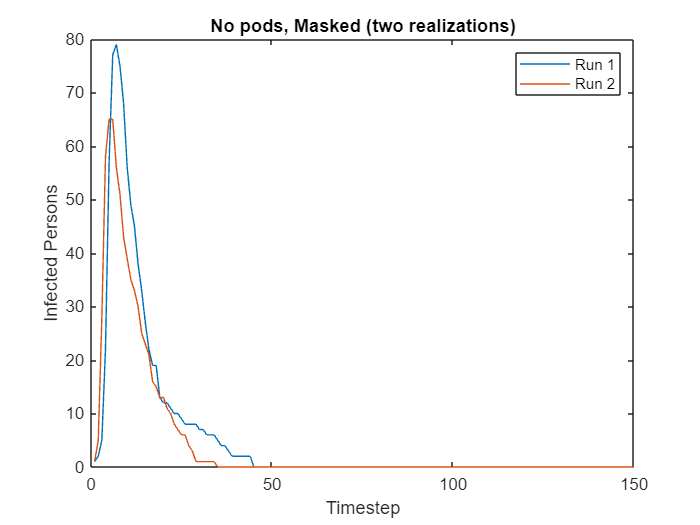

% Simulate another realization from the nopod model
[~, Ih_nopod_masked2, ~] = simulate_absir(M_nopod_masked, Iv1, tend, infection_rate, recovery_rate);
I_count_nopod_masked2 = sum(Ih_nopod_masked2, 1);

% Visually compare the two realizations from the *exact same model*
figure();
plot(I_count_nopod_masked, 'DisplayName', 'Run 1'); hold on;
plot(I_count_nopod_masked2, 'DisplayName', 'Run 2')
xlabel('Timestep')
ylabel('Infected Persons')
title('No pods, Masked (two realizations)')
legend()

Note that there's a bigger difference between realizations *from the same model*, as compared with the two realizations *from different models* shown above!

**It is complete nonsense to compare single realizations from random models.** This would be like rolling two dice, comparing them, and saying "this die *always* rolls a higher number than the other die."

**In order to make a sensible comparison between two random models, we have to compare ****summaries**** from ****multiple realizations****.** 

Let's run a sample from both models and compare summaries of those two samples.

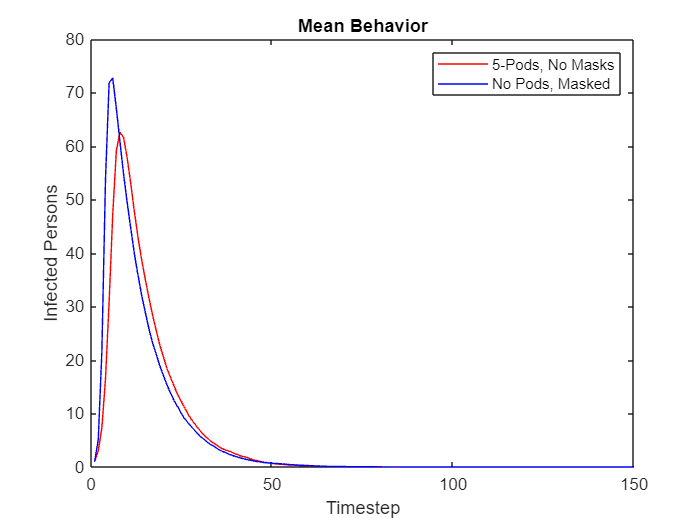

% Set up the sample study
n_realizations = 100;
I_ensemble_pod5_nomasks = zeros(tend, n_realizations);
I_ensemble_nopod_masked = zeros(tend, n_realizations);

% Generate the sample of results
rng(101)
for i = 1 : n_realizations
    % Run a single simulation
    [~, Ih_pod5_nomasks, ~] = simulate_absir(M_pod5_nomasks, Iv1, T_simulation, infection_rate, recovery_rate);
    [~, Ih_nopod_masked, ~] = simulate_absir(M_nopod_masked, Iv1, T_simulation, infection_rate, recovery_rate);
    % Summarize and store the infection history
    I_ensemble_pod5_nomasks(:, i) = sum(Ih_pod5_nomasks, 1);
    I_ensemble_nopod_masked(:, i) = sum(Ih_nopod_masked, 1);
end

% Summarize
I_mu_pod5_nomasks = mean(I_ensemble_pod5_nomasks, 2);
I_lo_pod5_nomasks = quantile(I_ensemble_pod5_nomasks, 0.25, 2); % Lower (25%) quantile
I_up_pod5_nomasks = quantile(I_ensemble_pod5_nomasks, 0.75, 2); % Upper (75%) quantile

I_mu_nopod_masked = mean(I_ensemble_nopod_masked, 2);
I_lo_nopod_masked = quantile(I_ensemble_nopod_masked, 0.25, 2); % Lower (25%) quantile
I_up_nopod_masked = quantile(I_ensemble_nopod_masked, 0.75, 2); % Upper (75%) quantile

% Visualize
figure();
plot(I_mu_pod5_nomasks, 'r', 'DisplayName', '5-Pods, No Masks'); hold on;
plot(I_mu_nopod_masked, 'b', 'DisplayName', 'No Pods, Masked');
xlabel('Timestep')
ylabel('Infected Persons')
title('Mean Behavior')
legend()

Comparing the mean between the two models shows us a **stable** difference between the two models. Here, we can see that on-average the masked scenario tends to produce a smaller infection peak. We also see that infection curves decay at about the same time.

The mean is not the only summary we can use. An upper quantile gives us a "worse case" look at the sample.

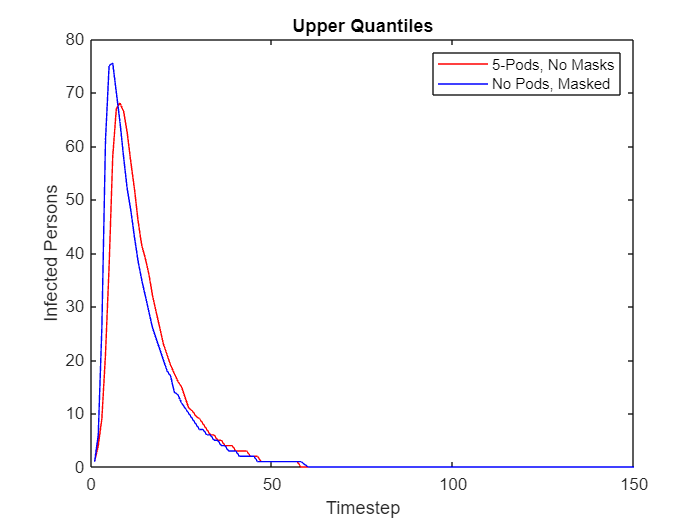

figure();
plot(I_up_pod5_nomasks, 'r', 'DisplayName', '5-Pods, No Masks'); hold on;
plot(I_up_nopod_masked, 'b', 'DisplayName', 'No Pods, Masked');
xlabel('Timestep')
ylabel('Infected Persons')
title('Upper Quantiles')
legend()

These results are in agreement with the mean results above: A slightly lower peak in the masking scenario, and a similar decay time.

### Relevant metrics

What if we wanted to make a decision about how many people should be in a pod? We could run multiple simulations across a variety of scenarios, but visualizing all of those infection curves would be a very messy way to report the data. Instead, we can use a relevant metric to summarize each scenario.

We saw above that the mean infection peak tends to respond to changes across the models, but the decay time does not. This suggests that the mean infection peak might be a good metric to consider to see differences across the models. The following code simulates results from a variety of pod sizes, computes the infection peak *within each realization*, and computes the mean across all infection peaks.

% Prepare several podding scenarios
M_pod20_nomasks = make_adj_pods(20, 5, 50) / 50;
M_pod10_nomasks = make_adj_pods(10, 10, 50) / 50;
M_pod5_nomasks = make_adj_pods(5, 20, 50) / 50;
M_pod2_nomasks = make_adj_pods(2, 50, 50) / 50;

% Reserve space
I_max_pod20_nomasks = zeros(1, n_realizations);
I_max_pod10_nomasks = zeros(1, n_realizations);
I_max_pod5_nomasks = zeros(1, n_realizations);
I_max_pod2_nomasks = zeros(1, n_realizations);
I_max_nopod_masked = zeros(1, n_realizations);

% Generate the sample of results
rng(101)
for i = 1 : n_realizations
    % Run a single simulation
    [~, Ih_pod20_nomasks, ~] = simulate_absir(M_pod20_nomasks, Iv1, T_simulation, infection_rate, recovery_rate);
    [~, Ih_pod10_nomasks, ~] = simulate_absir(M_pod10_nomasks, Iv1, T_simulation, infection_rate, recovery_rate);
    [~, Ih_pod5_nomasks, ~] = simulate_absir(M_pod5_nomasks, Iv1, T_simulation, infection_rate, recovery_rate);
    [~, Ih_pod2_nomasks, ~] = simulate_absir(M_pod2_nomasks, Iv1, T_simulation, infection_rate, recovery_rate);
    [~, Ih_nopod_masked, ~] = simulate_absir(M_nopod_masked, Iv1, T_simulation, infection_rate, recovery_rate);
    % Summarize and store the infection history
    I_max_pod20_nomasks(i) = max(sum(Ih_pod20_nomasks, 1));
    I_max_pod10_nomasks(i) = max(sum(Ih_pod10_nomasks, 1));
    I_max_pod5_nomasks(i) = max(sum(Ih_pod5_nomasks, 1));
    I_max_pod2_nomasks(i) = max(sum(Ih_pod2_nomasks, 1));
    I_max_nopod_masked(i) = max(sum(Ih_nopod_masked, 1));
end

Finally, let's compare the mean over all infection peaks, within each modeling scenario:

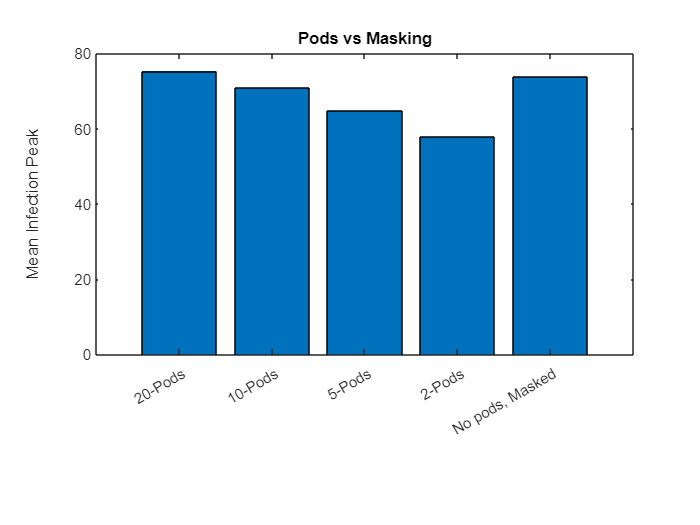

I_max_data = [
    I_max_pod20_nomasks;
    I_max_pod10_nomasks;
    I_max_pod5_nomasks;
    I_max_pod2_nomasks;
    I_max_nopod_masked
];
X = categorical({'20-Pods', '10-Pods', '5-Pods', '2-Pods', 'No pods, Masked'});
X = reordercats(X, {'20-Pods', '10-Pods', '5-Pods', '2-Pods', 'No pods, Masked'});

figure(); clf;
bar(X, mean(I_max_data, 2))
ylabel('Mean Infection Peak')
title('Pods vs Masking')

You'll make sense of these results in the last exercise!

### Exercise 8 / 9

Study the graph above, and answer the questions below.

- *Approximately* what pod size (how many people in a pod) is equivalent to no pods with universal masking?

-  *(Write your response here) *20 pods

- Which scenario *most* reduces the mean infection peak? Is this a realistic approach to controlling the spread of a disease?

-  *(Write your response here) *2-pods best reduces the mean infection peak. This isn't a very realistic approach since not everyone will want to only interact with one other person.

## Systematic Difference? Or Chance Alone?

To close this worksheet, let's take a closer look at the set of realizations we generated earlier. The following code shows all 100 realizations with their infection peak.

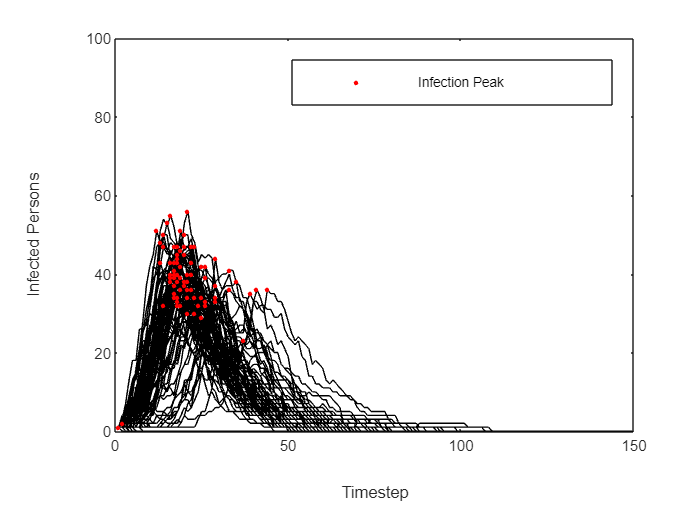

% Find the infection peaks
[I_max, T_max] = max(I_ensemble, [], 1);

% Visualize all peaks in-context
figure()
plot(I_ensemble, 'k-', 'LineWidth', 0.1, 'HandleVisibility', 'off'); hold on;
plot(T_max, I_max, 'r.', 'MarkerSize', 8, 'DisplayName', 'Infection Peak')
xlabel('Timestep')
ylabel('Infected Persons')
ylim([0 100])
legend()

Notice that there is a very wide spread in *when* the infection peak occurs! Some infections die out almost immediately—these are the red dots concentrated near Timestep == 1. The remaining peaks occur at a variety of times from ~20 to ~50.

When interpreting results, it is always tempting to assign some kind of *systematic reason* for observed differences. However, we should always keep in mind that *a systematic reason may not exist*. When there is no identifiable, systematic reason for a difference we say that a difference is due to "chance" (or "chance alone"). 

*Aside:* The "chance explanation" is closely related to the concept of a [null result](https://en.wikipedia.org/wiki/Null_result).

We saw `I_ensemble` earlier in this worksheet—**an identical model was used to generate every realization.** Keep this in mind as you complete the following exercise.

### Exercise 9 / 9

Find the time of the latest infection peak across the ensemble `I_ensemble`. Additionally, find the index of that time within the vector `T_max`. Use the Answer the questions below.

*Hint:* You may find it helpful to refer to the documentation for `max()` to figure this one out! Also, you can take a look at the code above for an example of using `max()` to find both the max value and the index of the max value.

% TODO: Find the timestep of the *latest* infection peak.
[T_latest, i_latest] = max(T_max) % Assign this value; use T_max (computed above) to do this

T_latest = 44

i_latest = 41

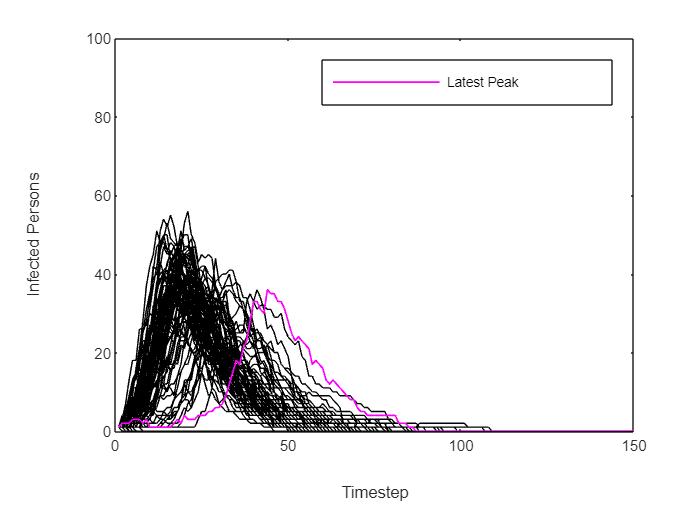


% NOTE: Do not edit this code; use this to check your work
% Visualize all peaks in-context
figure()
plot(I_ensemble, 'k-', 'LineWidth', 0.1, 'HandleVisibility', 'off'); hold on;
plot(I_ensemble(:, i_latest), 'm-', 'LineWidth', 1, 'DisplayName', 'Latest Peak')
xlabel('Timestep')
ylabel('Infected Persons')
ylim([0 100])
legend()

- When is the latest infection peak?

- *    (Write your response here) *Around timestep 50.

- What are the differences in the model (if any) used to generate the different results shown here?

- *    (Write your response here) *

- What property of the model explains the difference in the results shown here?

- *    (Write your response here) *The random infection and recovery rates.

- Do we need any differences in a model to explain the different infection peak times shown here? Can these differences be explained by chance alone? *Hint: Think of the Phillips (1996) paper we read in Worksheet 3.*

- *    (Write your response here)*

## Towards the Project!

This concludes Worksheet 4! You'll use the ideas of graph and agent-based models in your Project 2. Take a look at the Canvas page to learn more about your project options.

## Helper functions

These "helper functions" are used throughout the worksheet to simplify code.

Simulate the compartmental SIR model with different parameters.

function [t, Y] = compartmental(beta, gamma)
% We don't change these throughout the worksheet; fix them to constants
n_population = 100;
n_infected = 1;

% NB. The following is a *fancy* way of analyzing the compartmental SIR
% model. This formulates the model as a differential equation and uses some
% sophisticated Matlab machinery to simulate the model. I do this just to
% get some illustrative results with minimal lines of code.
%
% We do *not* expect you to be able to write this code.

% Set up the right hand side (RHS) of the model
odefun = @(t, y) [
    -beta * y(2) * y(1);
    +beta * y(2) * y(1) - gamma * y(2);
    +gamma * y(2)
];
% Simulate
Y1 = [n_population - n_infected; n_infected; 0];
[t, Y] = ode45(odefun, [0, 150], Y1);
end

Construct an adjacency matrix for a "podding" scenario; we learned how to do this in Worksheet 4, Part 3.

function M_res = make_adj_pods(n_per_pod, n_pods, pod_effect)
% Construct an adjacency matrix for a "podding" scenario
%
% Usage
%   M_res = make_adj_pods(n_per_pod, n_pods, infectivity)
%
% Arguments
%   n_per_pod  = number of persons per "pod"
%   n_pods     = total number of pods; total population = n_per_pod * n_pods
%   pod_effect = relative infectivity within pods; should be infectivity > 1
%
% Returns
%   M_res = adjacency matrix for desired graph
n_total = n_per_pod * n_pods;

% Create the "base matrix" with weak connections between all persons
M_res = ones(n_total, n_total) - eye(n_total);

% Add the pod structure
for i = 1:n_pods
    % Determine the slicing indices
    i0 = (i - 1) * n_per_pod + 1; ie = i0 + n_per_pod - 1;
    % Assign strong in-pod weights
    M_res(i0:ie, i0:ie) = pod_effect * M_res(i0:ie, i0:ie);
end

end